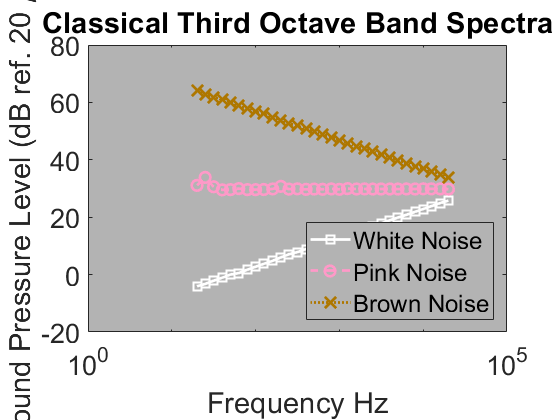

x1 = spatialPattern([1,500000],0);    % white noise has a linearly
                                      % increasing spectrum

x2 = spatialPattern([1,500000],-1);   % pink noise has a constant
                                      % spectrum

x3 = spatialPattern([1,500000],-2);   % brown noise has a linearly
                                      % increasing spectra

Fs=50000;         % (Hz) Sampling rate

num_x_filter=2;   % Number of times to filter the data.  Minimum value is 1
                  % typically a value of 2 to 10 at low
                  % frequencies (Fc < 100), num_x_filter=10 has a
                  % significant phase shift when using filter.

N=3;              % number of bands per octave.  

min_f=20;         % is the minimum frequency band to calculate (Hz).   

max_f=20000;       % is the maximum frequency band to calculate (Hz).  

sensor=1;         % acoustic microphone
                  % output is in dB

settling_time=1;  % (seconds) Time requiered for the filter to settle 
                  % usually 0.1 seconds or less.  
                  % This quantity is usually frequency dependent.  

filter_program=1; % 1 is for using the filter progam otherwise the
                  % filtfilt program is used.  
                  % default is filter_program=1 using filter progam.

resample_filter=1;

[fc_out1, SP_levels1]=Nth_oct_time_filter(x1, Fs, num_x_filter, N, min_f, max_f, sensor, settling_time, filter_program, resample_filter);
[fc_out2, SP_levels2]=Nth_oct_time_filter(x2, Fs, num_x_filter, N, min_f, max_f, sensor, settling_time, filter_program, resample_filter);
[fc_out3, SP_levels3]=Nth_oct_time_filter(x3, Fs, num_x_filter, N, min_f, max_f, sensor, settling_time, filter_program, resample_filter);

% Plot the results
figure(1); 
semilogx(fc_out1, SP_levels1, 'color', [1 1 1],         'linewidth', 2,                    'marker', 's', 'MarkerSize', 8);
hold on;
semilogx(fc_out2, SP_levels2, 'color', [1 0.6 0.784],   'linewidth', 2, 'linestyle', '--', 'marker', 'o', 'MarkerSize', 8);
semilogx(fc_out3, SP_levels3, 'color', [0.682 0.467 0], 'linewidth', 2, 'linestyle', ':',  'marker', 'x', 'MarkerSize', 12);
set(gca, 'color', 0.7*[1 1 1]);
legend({'White Noise', 'Pink Noise', 'Brown Noise'}, 'location', 'SouthEast');
xlabel('Frequency Hz', 'Fontsize', 28);
ylabel('Sound Pressure Level (dB ref. 20 \mu Pa)', 'Fontsize', 28);
title('Classical Third Octave Band Spectra', 'Fontsize', 40);
set(gca, 'Fontsize', 20);